**Practice Notebook Gabor Filters**

**Kuan-Min Lee**

**Gabor FIlter:**

**Basic Theory Explanation:**

Gabor filters can be defined as the following notation:

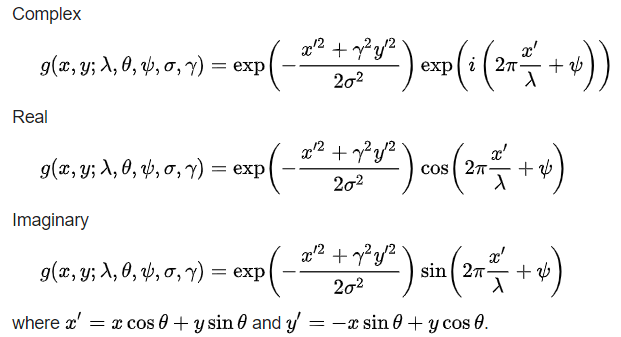

**Syntax:**

**[mag,phase]=imgaborfilt(A,wavelength,orientation,Name,Value)**

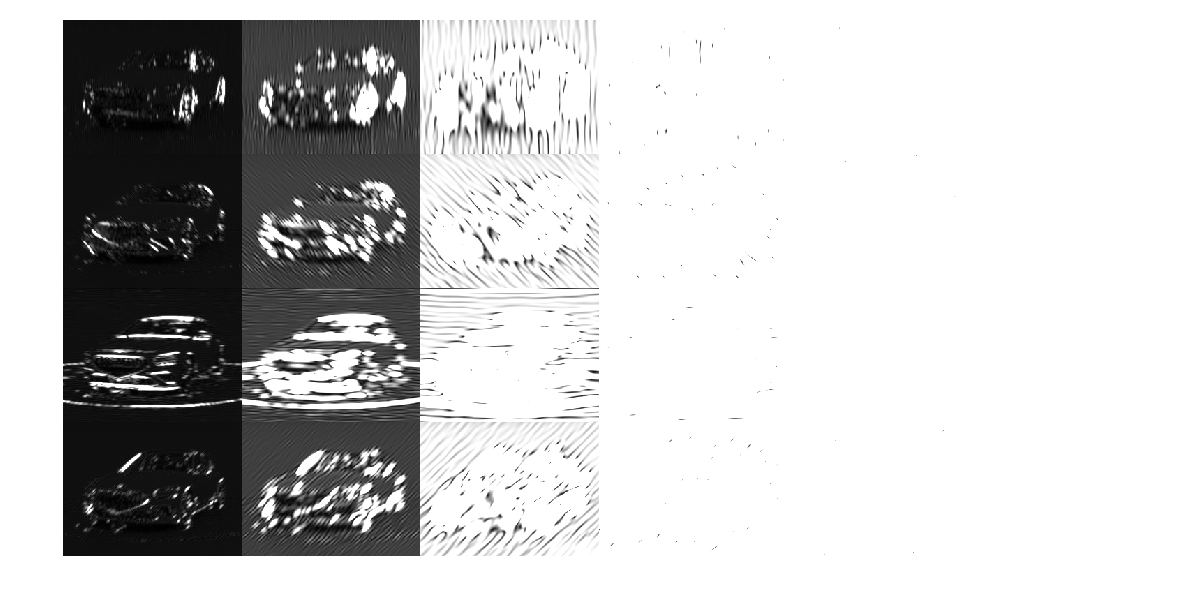

test_dir=("Testing_Images/"); % get the folder directory
img_dir=("car.jpg"); % get the image file name
ful_dir=strcat(test_dir,img_dir); % get the full directory
test_img=imread(ful_dir); % load testing image

wavelength = 2.^(0:5) * 3; % insert three different wavelengths
orientation = 0:45:135; % insert 4 different orientation
g = gabor(wavelength,orientation);
car_img_BW = im2gray(im2single(test_img)); % convert it into grayscale
gabormag = imgaborfilt(car_img_BW,g); % conduct gabor filtering

montage(gabormag,"size",[4 6])

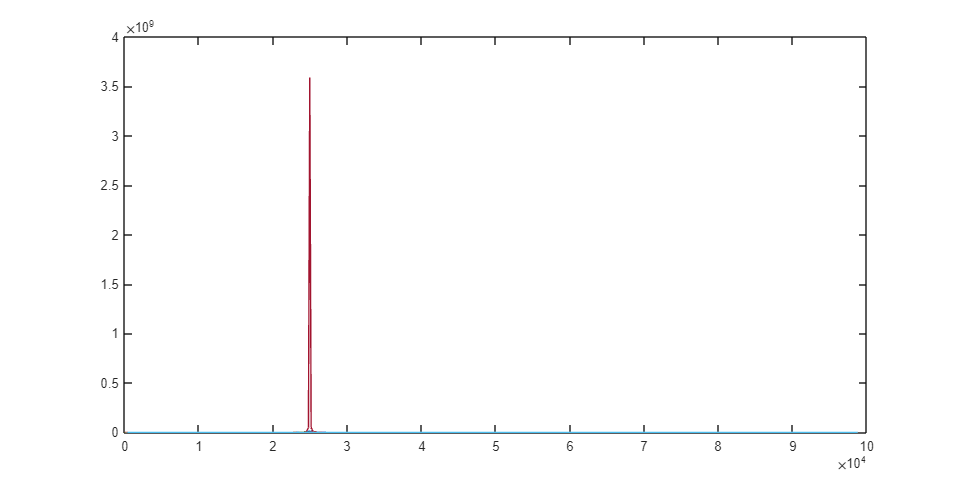

% view the power spectral density plot of the image
freq_img=img_spatio_freq(test_img);

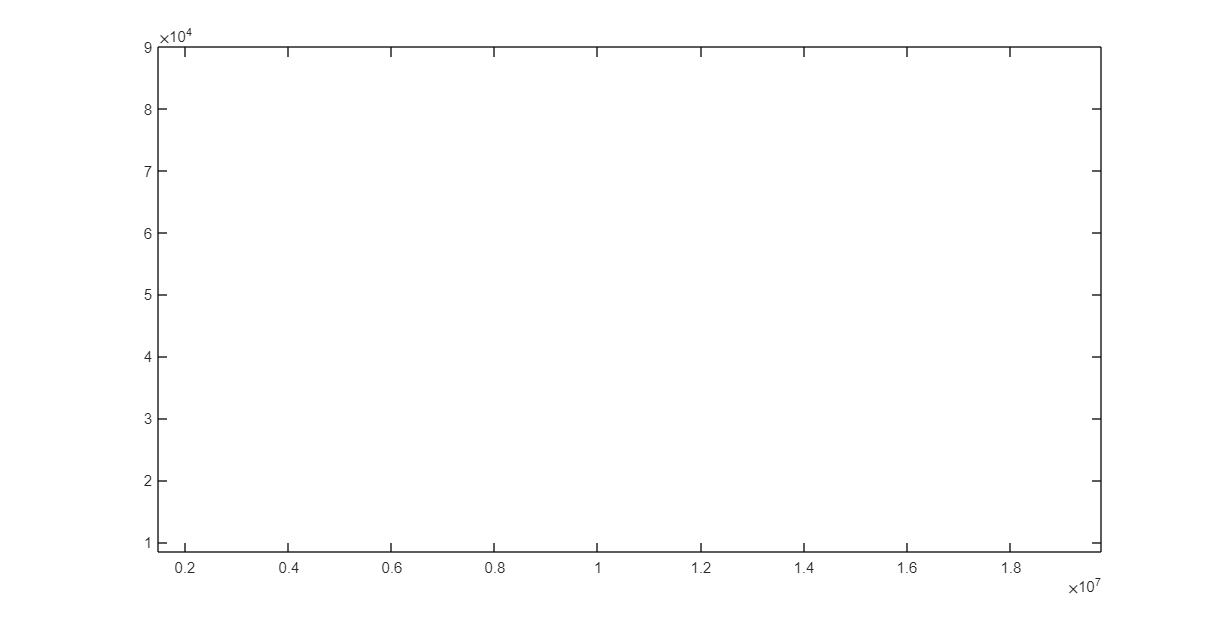

histogram(freq_img)

**Typical Usage:**

- Texture Analysis for image

- Edge Detection

- Feature Extraction

- Disparity Estimation